## Combined Exp

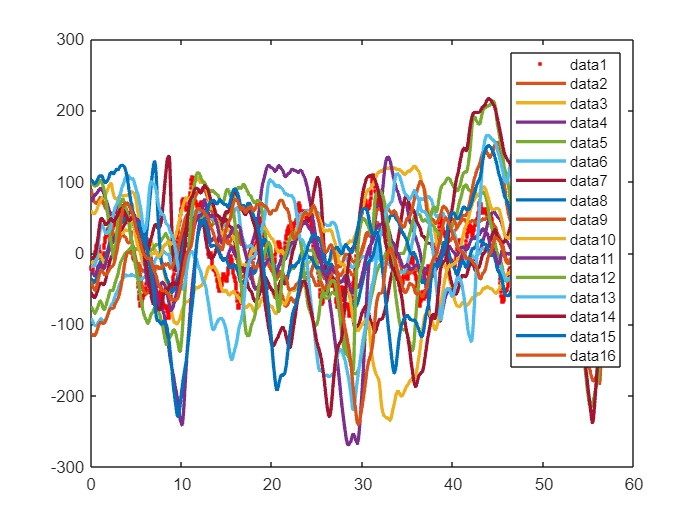

experiments = {
    % 'samsun low light window 7cm\7cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_04_22_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_08_20_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_10_11_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_11_50_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_13_41_2022_TRACK.xlsx',
    
    'Data\samsun low light window 21cm\21cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_46_43_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_48_50_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_50_57_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_54_12_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_56_25_2022_TRACK.xlsx',
    
    'Data\samsun low light window 14cm\14cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_54_05_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_56_51_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_00_01_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_02_22_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_04_12_2022_TRACK.xlsx',
   
    'Data\samsun low light nowindow 21cm\21cm\trial01_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_03_18_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_07_26_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial04_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_09_31_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial05_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_11_33_2022_TRACK.xlsx',
    };

% readtable("samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx")

fishes = [];

for experimentIdx = 1:length(experiments)
    experiment = experiments{experimentIdx};
    table = readtable(experiment);
    fish = table.Fish;
    fish = fish(76:end);
    fishes = [fishes detrend(fish)];
end

table_0 = readtable(experiments{1});
cage = table_0.Cage;
cage = cage(76:end);
cage = detrend(cage);

Fs = 25;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(cage);             % Length of signal
t = (0:L-1)*T;        % Time vector
f = Fs/L*(0:L-1);

figure,
hold on; box on;
plot(t, cage, '.r', 'LineWidth', 4);

for fish = fishes
    Fs = 25;
    t = 0:1/Fs:(length(fish)-1)/Fs;

    plot(t, fish, 'LineWidth', 2);
end

legend()

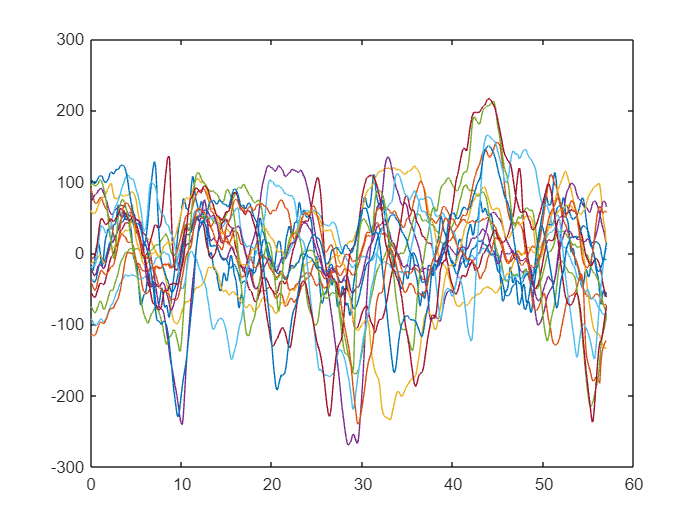

y = fishes;
u = cage;
num_outputs = length(y(1,:));

figure, hold on, box on,
plot(t, u, t, y);

% Create an iddata object with your data
data = iddata(y, u, t(2) - t(1), 'ExperimentName', experiments);

% figure, box on,
% plot(data);

% Initialize cell array for storing models
G_ests = cell(1, num_outputs);

% Define the transfer function structure for the model
K_initial = 1; % Initial guess for K
a_initial = 1; % Initial guess for a
tau_initial = 0.5; % Initial guess for tau

% Loop through each output to estimate the model
for i = 1:num_outputs
    % Create idtf model with initial parameter values
    G0 = idtf(K_initial, [1 a_initial], 'InputDelay', tau_initial);

    % Estimate the model parameters for each output
    G_ests{i} = pem(iddata(y(:, i), u, t(2) - t(1)), G0);
end

% Display the estimated models
for i = 1:num_outputs
    G_ests{i}
end

ans =
  From input "u1" to output "y1":
                  1.758
  exp(-0.5*s) * ---------
                s + 4.065
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                 
Estimated using PEM on time domain data.
Fit to estimation data: 14.79%          
FPE: 1227, MSE: 1222                    
 
Model Properties

ans =
  From input "u1" to output "y1":
                  0.3093
  exp(-0.5*s) * ----------
                s + 0.3721
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Nu

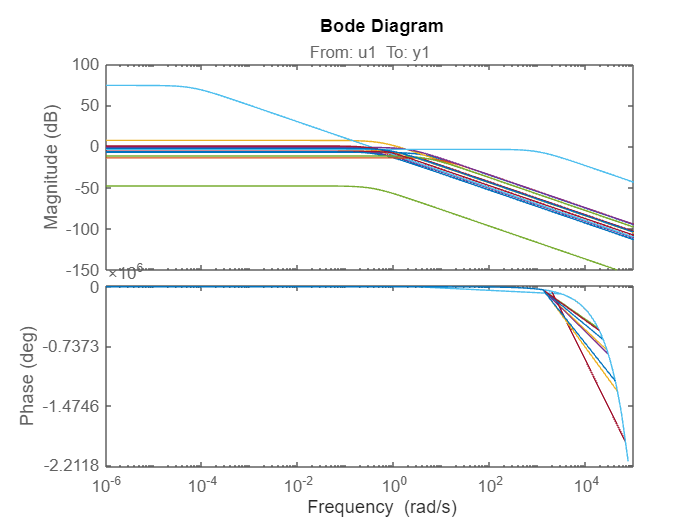

figure, hold on, box on,
for i = 1:num_outputs
    h = bodeplot(G_ests{i});
    % showConfidence(h,3)
end

% Initialize cell array for storing sim outputs
y_sims = zeros(size(y));

% Simulate the model output
for i = 1:num_outputs
    y_sims(:, i) = lsim(G_ests{i}, u, t);
end

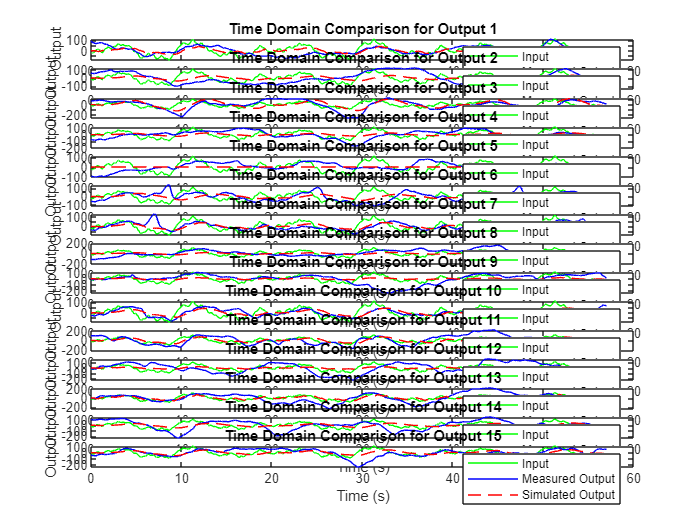

% Plot the measured output vs. simulated output in the time domain
figure; hold on,
for i = 1:num_outputs
    subplot(num_outputs, 1, i);
    plot(t, u, 'g', t, y(:, i), 'b', t, y_sims(:, i), 'r--');
    legend('Input', 'Measured Output', 'Simulated Output');
    xlabel('Time (s)');
    ylabel('Output');
    title(['Time Domain Comparison for Output ' num2str(i)]);
end

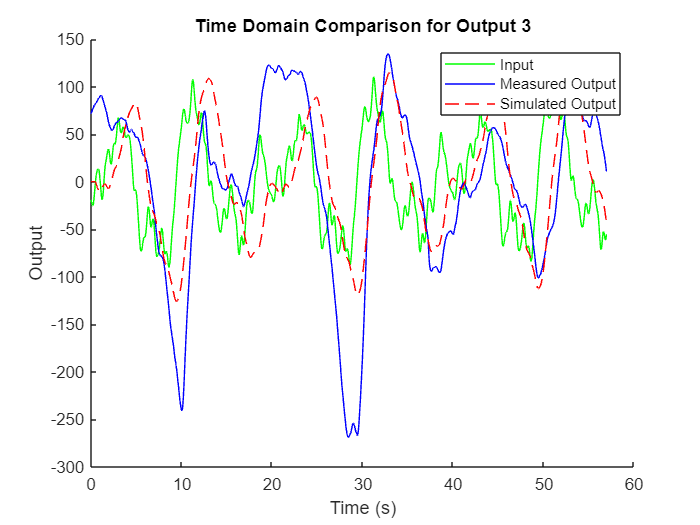

figure; hold on,
i = 3;
plot(t, u, 'g', t, y(:, i), 'b', t, y_sims(:, i), 'r--');
legend('Input', 'Measured Output', 'Simulated Output');
xlabel('Time (s)');
ylabel('Output');
title(['Time Domain Comparison for Output ' num2str(i)]);

% Compute the frequency response of the measured data using spectral analysis
data_fft = cell(1, num_outputs);
for i = 1:num_outputs
    data_fft{i} = spa(iddata(y(:, i), u, t(2) - t(1)));
end

% Compute the frequency response of the identified models
mag_estimated = cell(1, num_outputs);
phase_estimated = cell(1, num_outputs);
mag_measured = cell(1, num_outputs);
phase_measured = cell(1, num_outputs);
wout = [];

% Loop through each output to compute frequency responses
for i = 1:num_outputs
    % Compute the frequency response of the identified models
    [mag_estimated{i}, phase_estimated{i}, wout] = bode(G_ests{i});

    % Extract magnitude and phase from spa result
    [mag_measured{i}, phase_measured{i}] = bode(data_fft{i}, wout);

    % Convert magnitudes and phases to vectors for plotting
    mag_measured{i} = squeeze(mag_measured{i});
    phase_measured{i} = squeeze(phase_measured{i});
    mag_estimated{i} = squeeze(mag_estimated{i});
    phase_estimated{i} = squeeze(phase_estimated{i});
end

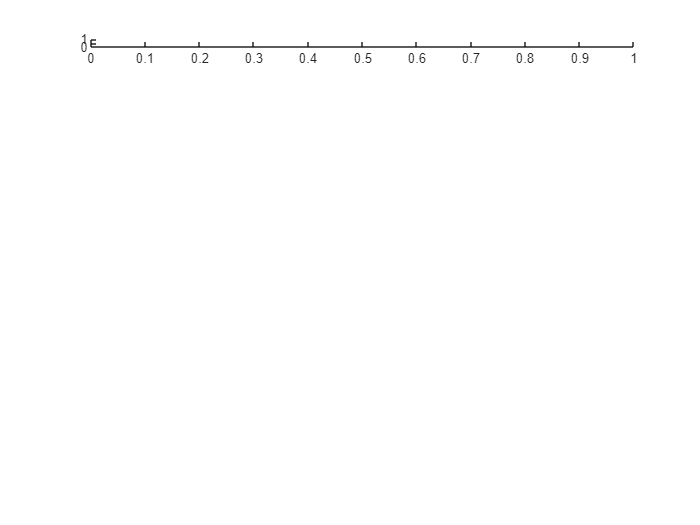

Error using semilogx
Vectors must be the same length.

% Plot the frequency response comparison
figure;
for i = 1:num_outputs
    subplot(num_outputs, 1, i);
    semilogx(wout, 20*log10(mag_measured{i}), 'b', wout, 20*log10(mag_estimated{i}), 'r--');
    legend(['Measured Data Output ' num2str(i)], ['Identified Model Output ' num2str(i)]);
    xlabel('Frequency (rad/s)');
    ylabel(['Magnitude (dB) for Output ' num2str(i)]);
    title(['Frequency Domain Comparison for Output ' num2str(i)]);
end

i = 3;

data_fft = spa(iddata(y(:, i), u, t(2) - t(1)))

data_fft =

IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s), and the spectra for disturbances at the outputs.
Response data and disturbance spectra are available at 128 frequency points, ranging from 0.6136 rad/s to 78.54 rad/s.
 
Sample time: 0.04 seconds
Output channels: 'y1'
Input channels: 'u1'
Status:                                 
Estimated using SPA on time domain data.
 
Model Properties


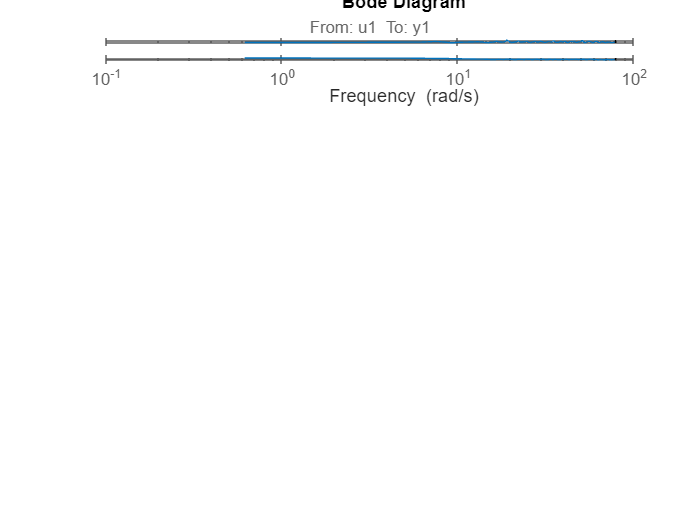

bode(data_fft)

[mag_estimated, phase_estimated, wout] = bode(G_ests{i})

mag_estimated = mag_estimated(:,:,1) =

    2.3045


mag_estimated(:,:,2) =

    2.3044


mag_estimated(:,:,3) =

    2.3043


mag_estimated(:,:,4) =

    2.3040


mag_estimated(:,:,5) =

    2.3037


mag_estimated(:,:,6) =

    2.3033


mag_estimated(:,:,7) =

    2.3027


mag_estimated(:,:,8) =

    2.3019


mag_estimated(:,:,9) =

    2.3008


mag_estimated(:,:,10) =

    2.2993


mag_estimated(:,:,11) =

    2.2972


mag_estimated(:,:,12) =

    2.2944


mag_estimated(:,:,13) =

    2.2906


mag_estimated(:,:,14) =

    2.2854


mag_estimated(:,:,15) =

    2.2784


mag_estimated(:,:,16) =

    2.2689


mag_estimated(:,:,17) =

    2.2675


mag_estimated(:,:,18) =

    2.2561


mag_estimated(:,:,19) =

    2.2389


mag_estimated(:,:,20) =

    2.2161


mag_estimated(:,:,21) =

    2.1859


mag_estimated(:,:,22) =

    2.1466


mag_estimated(:,:,23) =

    2.0961


mag_estimated(:,:,24) =

    2.0325


mag_estimated(:,:,25) =

    1.9542


mag_estimated(:,:,26) =

    1.8605


mag_e

phase_estimated = phase_estimated(:,:,1) =

   -1.3315


phase_estimated(:,:,2) =

   -1.4599


phase_estimated(:,:,3) =

   -1.7071


phase_estimated(:,:,4) =

   -1.9961


phase_estimated(:,:,5) =

   -2.3341


phase_estimated(:,:,6) =

   -2.7292


phase_estimated(:,:,7) =

   -3.1911


phase_estimated(:,:,8) =

   -3.7309


phase_estimated(:,:,9) =

   -4.3618


phase_estimated(:,:,10) =

   -5.0989


phase_estimated(:,:,11) =

   -5.9598


phase_estimated(:,:,12) =

   -6.9648


phase_estimated(:,:,13) =

   -8.1375


phase_estimated(:,:,14) =

   -9.5046


phase_estimated(:,:,15) =

  -11.0967


phase_estimated(:,:,16) =

  -12.9479


phase_estimated(:,:,17) =

  -13.2027


phase_estimated(:,:,18) =

  -15.0962


phase_estimated(:,:,19) =

  -17.5827


phase_estimated(:,:,20) =

  -20.4505


phase_estimated(:,:,21) =

  -23.7428


phase_estimated(:,:,22) =

  -27.5003


phase_estimated(:,:,23) =

  -31.7568


phase_estimated(:,:,24) =

  -36.5349


phase_estimated(:,:,25) =

  -4

wout =     0.0100
    0.0110
    0.0128
    0.0150
    0.0175
    0.0205
    0.0240
    0.0280
    0.0328
    0.0383


[mag_measured, phase_measured] = bode(data_fft, wout)

mag_measured = mag_measured(:,:,1) =

   NaN


mag_measured(:,:,2) =

   NaN


mag_measured(:,:,3) =

   NaN


mag_measured(:,:,4) =

   NaN


mag_measured(:,:,5) =

   NaN


mag_measured(:,:,6) =

   NaN


mag_measured(:,:,7) =

   NaN


mag_measured(:,:,8) =

   NaN


mag_measured(:,:,9) =

   NaN


mag_measured(:,:,10) =

   NaN


mag_measured(:,:,11) =

   NaN


mag_measured(:,:,12) =

   NaN


mag_measured(:,:,13) =

   NaN


mag_measured(:,:,14) =

   NaN


mag_measured(:,:,15) =

   NaN


mag_measured(:,:,16) =

   NaN


mag_measured(:,:,17) =

   NaN


mag_measured(:,:,18) =

   NaN


mag_measured(:,:,19) =

   NaN


mag_measured(:,:,20) =

   NaN


mag_measured(:,:,21) =

   NaN


mag_measured(:,:,22) =

   NaN


mag_measured(:,:,23) =

   NaN


mag_measured(:,:,24) =

   NaN


mag_measured(:,:,25) =

   NaN


mag_measured(:,:,26) =

   NaN


mag_measured(:,:,27) =

   NaN


mag_measured(:,:,28) =

   NaN


mag_measured(:,:,29) =

    0.4220


mag_measured(:,:,30) =

    0.428

phase_measured = phase_measured(:,:,1) =

   NaN


phase_measured(:,:,2) =

   NaN


phase_measured(:,:,3) =

   NaN


phase_measured(:,:,4) =

   NaN


phase_measured(:,:,5) =

   NaN


phase_measured(:,:,6) =

   NaN


phase_measured(:,:,7) =

   NaN


phase_measured(:,:,8) =

   NaN


phase_measured(:,:,9) =

   NaN


phase_measured(:,:,10) =

   NaN


phase_measured(:,:,11) =

   NaN


phase_measured(:,:,12) =

   NaN


phase_measured(:,:,13) =

   NaN


phase_measured(:,:,14) =

   NaN


phase_measured(:,:,15) =

   NaN


phase_measured(:,:,16) =

   NaN


phase_measured(:,:,17) =

   NaN


phase_measured(:,:,18) =

   NaN


phase_measured(:,:,19) =

   NaN


phase_measured(:,:,20) =

   NaN


phase_measured(:,:,21) =

   NaN


phase_measured(:,:,22) =

   NaN


phase_measured(:,:,23) =

   NaN


phase_measured(:,:,24) =

   NaN


phase_measured(:,:,25) =

   NaN


phase_measured(:,:,26) =

   NaN


phase_measured(:,:,27) =

   NaN


phase_measured(:,:,28) =

   NaN


phase_measur


% semilogx(wout, 20*log10(mag_measured), 'b', wout, 20*log10(mag_estimated), 'r--');

figure, hold on,

for i = 3:3
    h = bodeplot(G_ests{i});
    showConfidence(h,3)
end

figure,
h = spectrumplot(G_ests{3});
showConfidence(h,3)